pathToImages = '/home/enes/Desktop/Derin Öğrenme/Traffic_Sign_CNN_Matlab/Data/train';
imds = imageDatastore(pathToImages,"IncludeSubfolders",true,"LabelSource","foldernames");

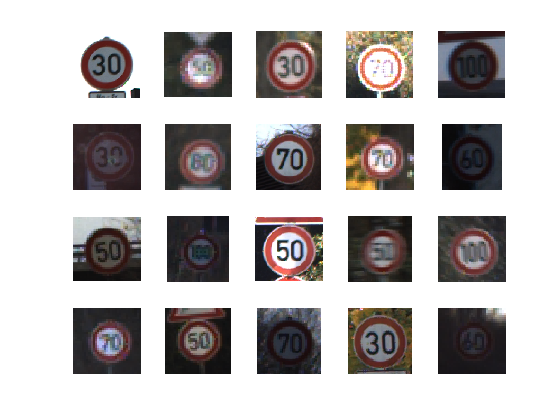

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds);

img = readimage(imds,51);
size(img);

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.80,'randomize');

layers = [
    imageInputLayer([28 28 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

trainds = augmentedImageDatastore([28 28], imdsTrain);
valds = augmentedImageDatastore([28 28], imdsValidation);


options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',valds, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');


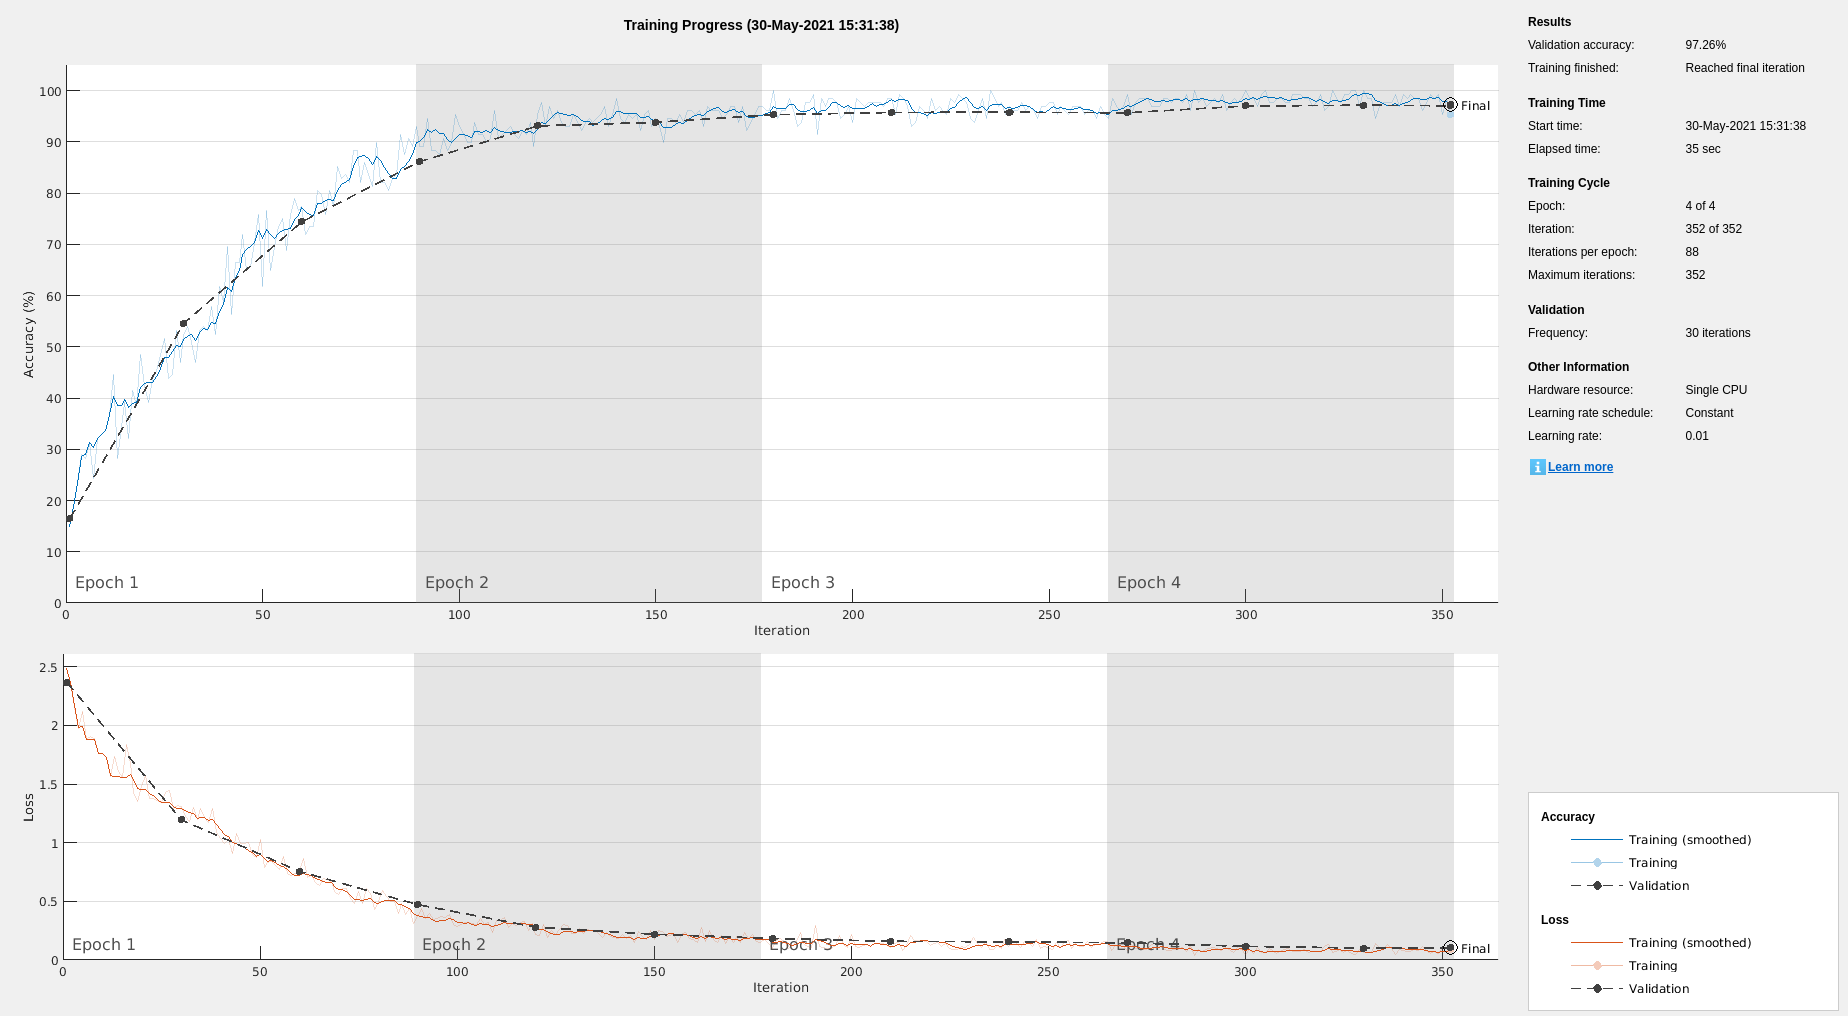

net = trainNetwork(trainds,layers,options);